## Exercise 2

#### Task 1

clearvars, clc, close all
load('EMG_Practical2.mat', 'SIG', 'MUPulses', 'fsamp');

EMG = vertcat(SIG{:});

Convert each MUPulses into a binary code

length(EMG(1,:))

ans = 69540

binary = zeros(length(MUPulses), length(EMG(1,:)));
for i = 1:length(MUPulses)
    MUPulse = MUPulses{i};
    for j = 1:length(MUPulse)
       index = MUPulse(j);
       binary(i, index) = 1;        
    end
end

#### Task 2

1. Compute the cumulative spike train (CST) which is the sum of these binary codes for all motor units.

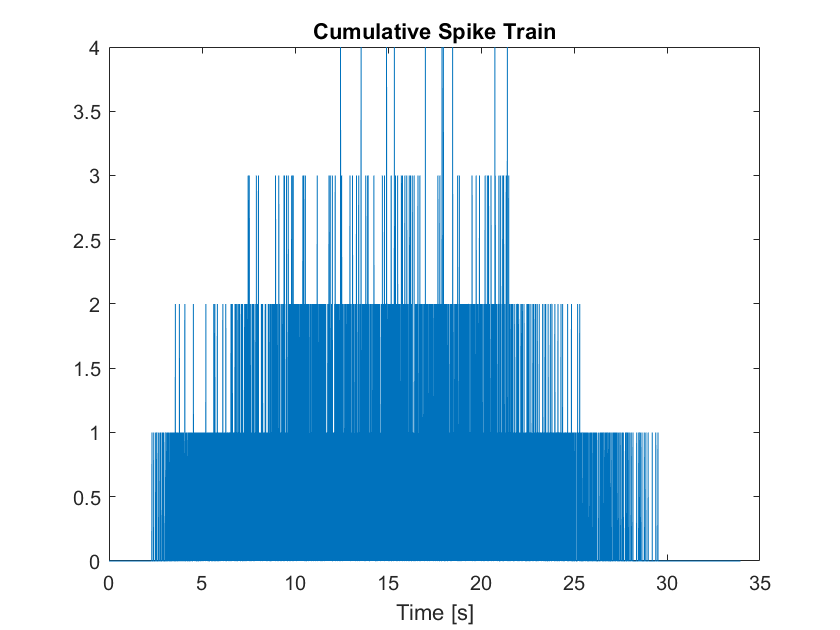

cst = sum(binary);
time = 0:1/fsamp:(length(EMG(1,:))-1)/fsamp;
fig_cst = figure;
plot(time,cst);    
title("Cumulative Spike Train")
xlabel("Time [s]")
saveas(fig_cst, "cst.jpg")

2. Compute the average number discharge rate per second (firings/second)

time_duration = [0.05, 0.1, 0.2];
average = [];
fig_avg_discharge = figure;
for i= 1:length(time_duration)        
    number_samples = round(fsamp*time_duration(i));        
    start = 1;
    ende = number_samples;
    for j = 1:(length(cst))
        if ende <= length(cst)
            signal = cst(start:ende);
            start = start+1;
            ende = ende+1;
            average(end+1) = sum(signal)/number_samples;
        end
    end  
    disp("Duration: " + time_duration(i) + "ms");
    time = 0:1/fsamp:(length(average)-1)/fsamp;
    subplot(2,2,i);
    plot(time, average);
    title("Window size: " + time_duration(i) + "s")
    xlabel("Time [s]") 
    average = [];
end

Duration: 0.05ms
Duration: 0.1ms
Duration: 0.2ms


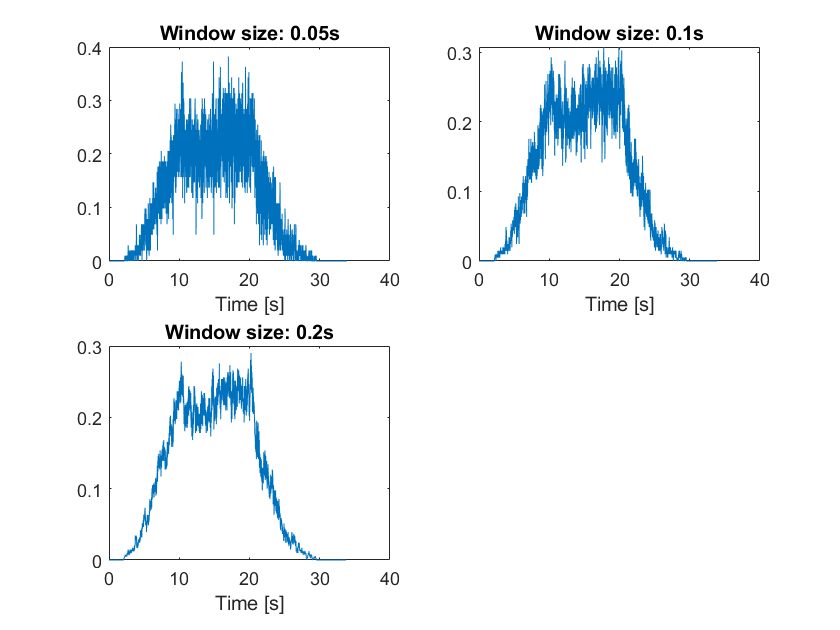


saveas(fig_avg_discharge, "Average_discharge.jpg")

#### Task 3

Perform exercise for MUPulse 1

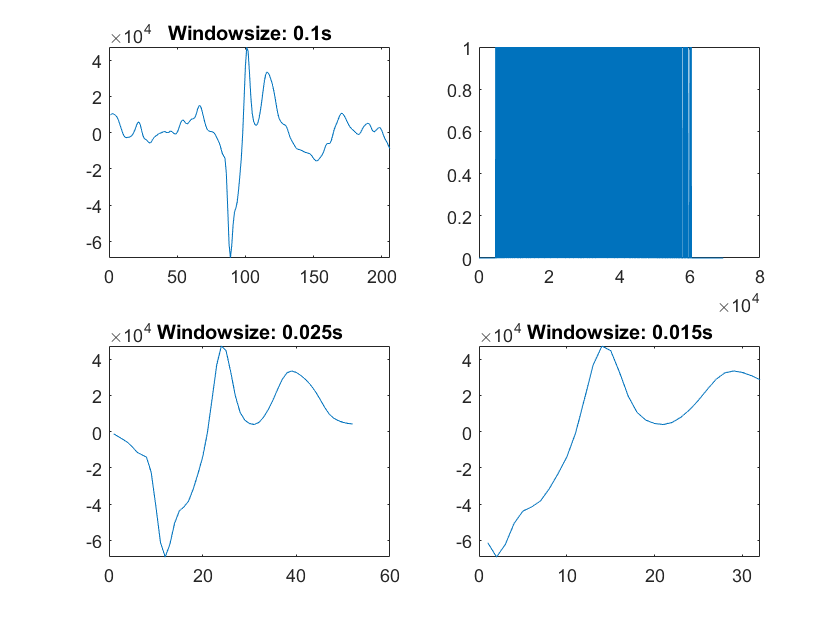

plot(SIG{1})
plot(binary(1,:))

resp = binary(1,:);
windowSize = [0.1, 0.05, 0.025, 0.015];
windowSize_sample = round(fsamp*windowSize);

windowSize_sample =    205   102    51    31


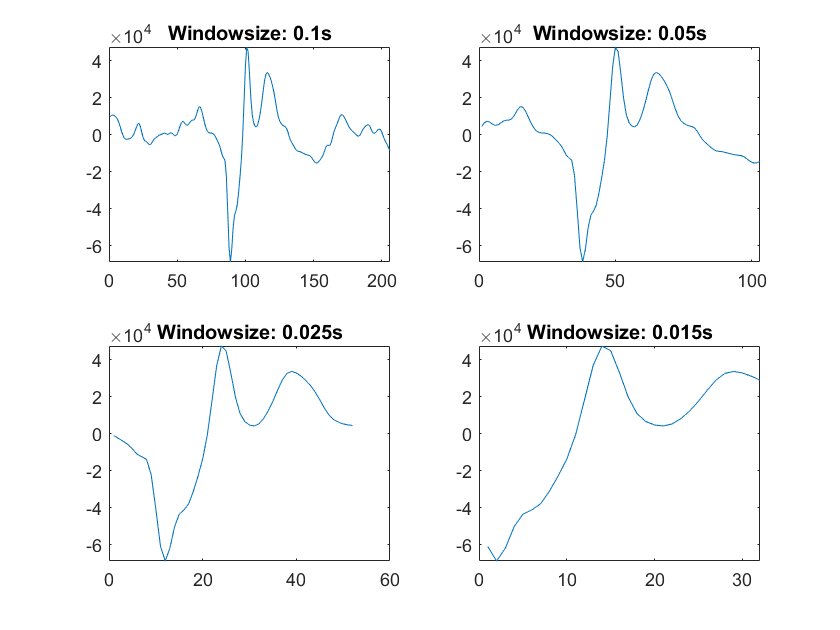

nEvs = sum(resp);
evIdx = find(resp);
avg = 0;

fig_sta = figure;
for i = 1:length(windowSize)
    % For each event
    for w = 1:nEvs 
        % Find the indexes of the time window preceding the event
        wIdx = round(evIdx(w) - windowSize_sample(i)/2) : round(evIdx(w) + windowSize_sample(i)/2);
        % Add the stim from this window to the average
        avg = avg + SIG{1}(wIdx);
    end
    subplot(2,2,i);
    plot(avg);
    title("Windowsize: " + windowSize(i) + "s")
    avg = 0;
end

saveas(fig_sta, "STA.jpg")

#### Task 4

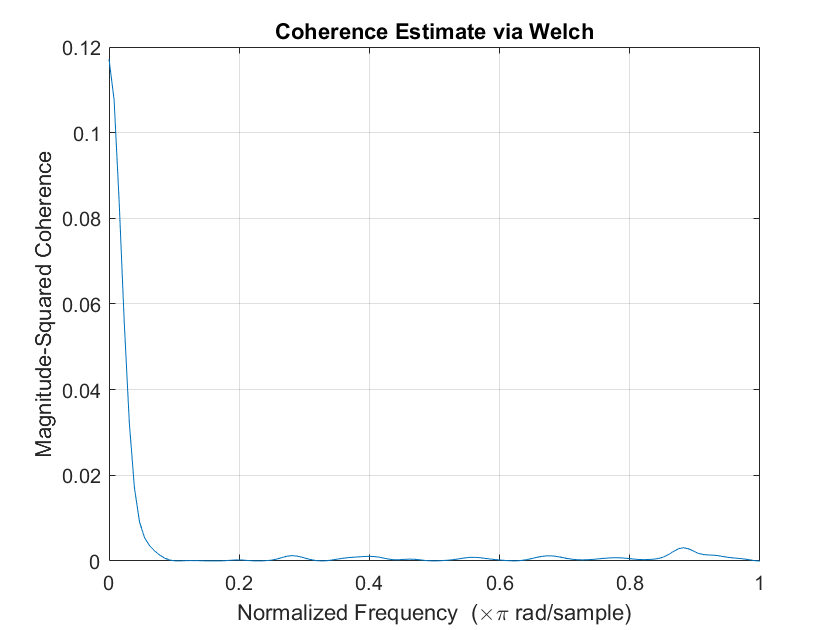

cohe = 0;
fig_coherence = figure;
mscohere(binary(1,:),binary(2,:), hanning(50))
saveas(fig_coherence, "Coherence.jpg")